load('G:\Order\MyMathLib\MyMatlabLib\HSI\Tua.mat')
load('G:\Order\MyMathLib\MyMatlabLib\HSI\Iph.mat')

load("G:\Order\MyMathLib\MyMatlabLib\HSI\IDS_COLORCHECK_1020-1223.mat");
image(rgb)
Xmin = 270;
Xmax = 333;
Ymin = 11;
Ymax = 120;
% image(rgb(Ymin:Ymax,Xmin:Xmax,:))
lambda = 400:400/30:800;
WL = 500:1:800;
rgb = rgb(Ymin:Ymax,Xmin:Xmax,:);
Ymin = 1392-120;
Ymax = 1392-11;
rad = rad(Xmin:Xmax,Ymin:Ymax,:);
RAD = zeros(Xmax-Xmin+1,Ymax-Ymin+1,length(WL));
TUA = zeros(Xmax-Xmin+1,Ymax-Ymin+1,length(WL));
IPH = zeros(Xmax-Xmin+1,Ymax-Ymin+1,length(WL));

for i = 1:Xmax-Xmin+1
    for j = 1:Ymax-Ymin+1
        s = reshape(rad(i,j,:),1,31);
        S = interp1(lambda, s, WL,"pchip");
        RAD(i,j,:) = S;
        TUA(i,j,:) = S*Tua;
        IPH(i,j,:) = S*Iph;
    end
end

clf;
figure(2);
HSV = jet;

MAX = max(max(max(IPH)));
for i=1:30:301
    color = HSV(ceil((302-i)/300*255),:)*0.3;
    Grad = 0:0.8/255:0.8;
    CM = ones(256,3)-repmat([1,1,1]-color,256,1).*repmat(Grad',1,3);
    subplot(4,3,(i+29)/30);
%     normImg = RAD(:,:,i)/MAX*256;
    normImg = IPH(:,:,i)/MAX*256;
    [x,y,z] = size(normImg);
    imshow(normImg,CM,'border','tight','initialmagnification','fit');
    axis normal;
    set (gcf,'Position',[0,0,x,y]);
    saveas(2, ['save',num2str(i+499),'.jpg']);
end

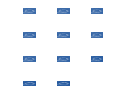

MAX = max(max(max(IPH)));
for i=1:30:301
    color = [24 80 154]./256;
    Grad = 0.2:0.8/255:1.0;
    CM = ones(256,3)-repmat([1,1,1]-color,256,1).*repmat(Grad',1,3);
    subplot(4,3,(i+29)/30);
%     normImg = RAD(:,:,i)/MAX*256;
    normImg = IPH(:,:,i)/MAX*256;
    [x,y,z] = size(normImg);
    imshow(normImg,CM,'border','tight','initialmagnification','fit');
    axis normal;
    set (gcf,'Position',[0,0,x,y]);
    saveas(2, ['save',num2str(i+499),'.jpg']);
end

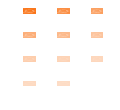

MAX = max(max(max(TUA)));
for i=1:30:301
    color = [251 112 16]./256;
    Grad = 0.2:0.8/255:1.0;
    CM = ones(256,3)-repmat([1,1,1]-color,256,1).*repmat(Grad',1,3);
    subplot(4,3,(i+29)/30);
%     normImg = RAD(:,:,i)/MAX*256;
    normImg = TUA(:,:,i)./MAX*256;
    [x,y,z] = size(normImg);
    imshow(normImg,CM,'border','tight','initialmagnification','fit');
    axis normal;
    set (gcf,'Position',[0,0,x,y]);
    saveas(2, ['save',num2str(i+499),'.jpg']);
end